
DIPlib 2.9 (Oct 17 2017 - Release [on Cygwin (with OpenMP)])
    Scientific Image Analysis Library
    Quantitative Imaging Group, Delft University of Technology 1995-2017
    info@diplib.org


dipIO 2.9 (Oct 17 2017 - Release)
    File I/O library for DIPlib
    Quantitative Imaging Group, Delft University of Technology 1999-2017
    info@diplib.org



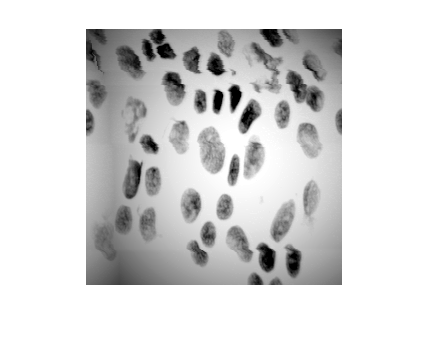

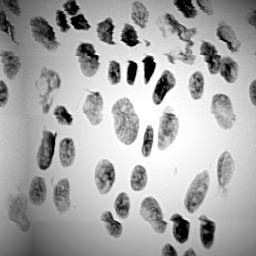

Displayed in figure 13


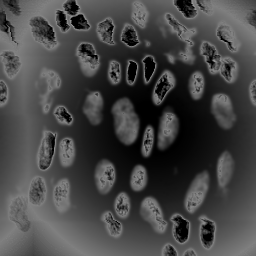

Displayed in figure 14


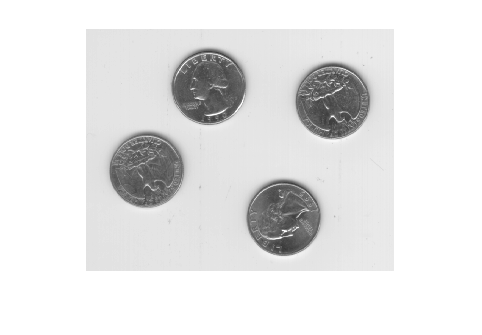

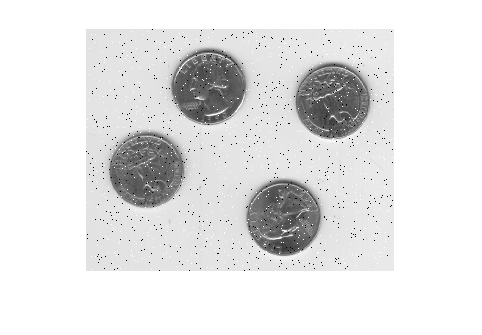

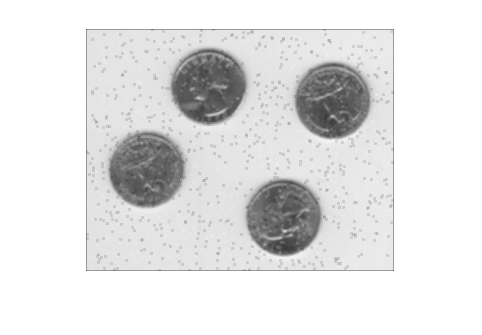

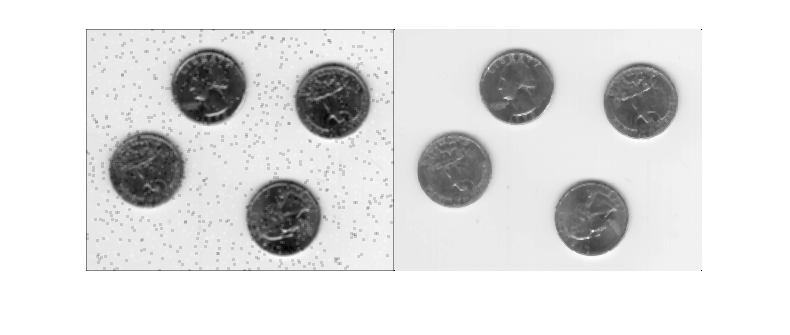

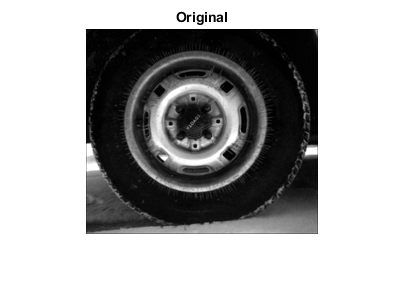

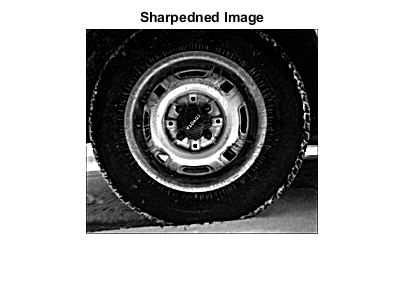

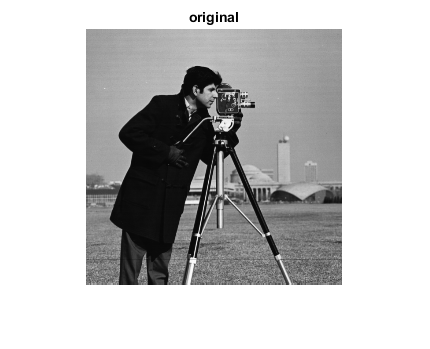

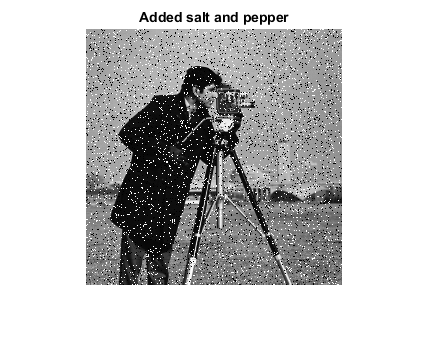

dipstart

Q1: Dilation and Erosion

**Dilation**: I first show the original image, then I use function "strel" to create diamond shape structure element. Finally, I use function "imdialate" to dilate the image and show it as below. 

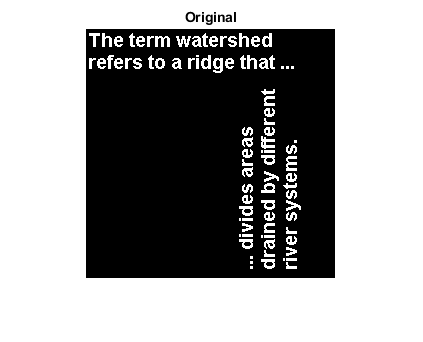

Image1 = imread('text.png');
imshow(Image1),title('Original')

seDiamond = strel('diamond',1)

seDiamond = strel is a diamond shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


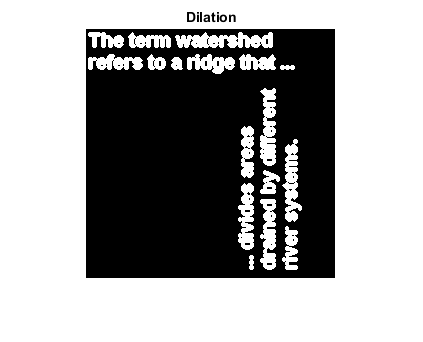

Dilation= imdilate(Image1,seDiamond);
imshow(Dilation), title('Dilation')

**Erosion**: I first show the original image, then I create a flast, line shaped structure element using "strel" function. Finally, I use function "imerode" to erode the image then show it. 

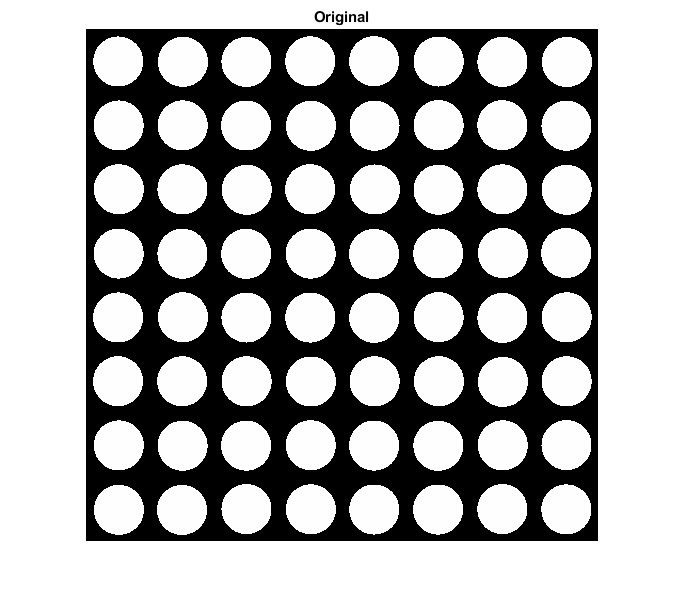

Image2 = imread('sdisk3.tif');
imshow(Image2), title('Original')

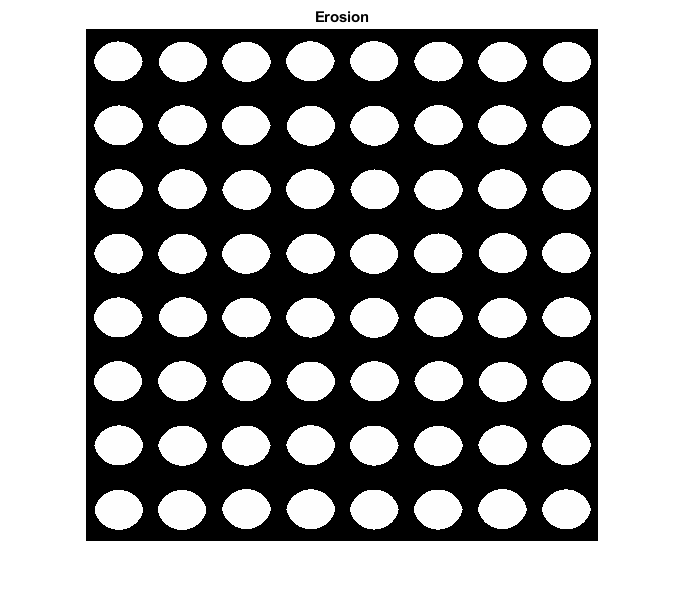

seSquare = strel('line',11,90);
Erosion = imerode(Image2,seSquare);
imshow(Erosion), title('Erosion')

**Q3: **write down all the commands you used in perform **the part 7 binary morphology.**

Ans:

- Binary opening: I create disk shaped structure element with a raidus of 3 pixels by using "strel", then I use "imopen" function to perform binary open to the object in the image.

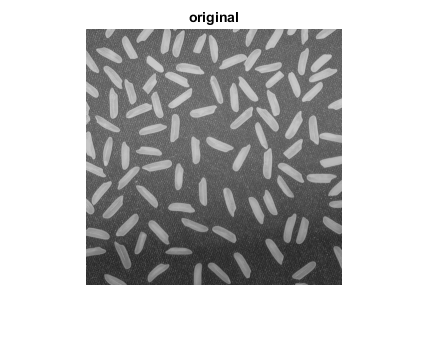

Image3 = imread('rice.png');
imshow(Image3), title('original')

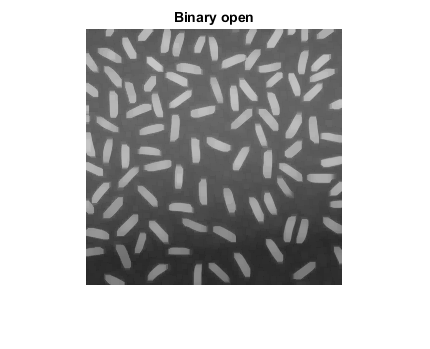

se = strel('disk',3);
MorphologyOpen = imopen(Image3,se);
imshow(MorphologyOpen), title('Binary open')

- Binary closing: I also create disk shaped structure using the same method but with the radius of 7 pixels (so the largest gap in the object in the picture can be filled), then I use "imclose" to perform binary close to the object.

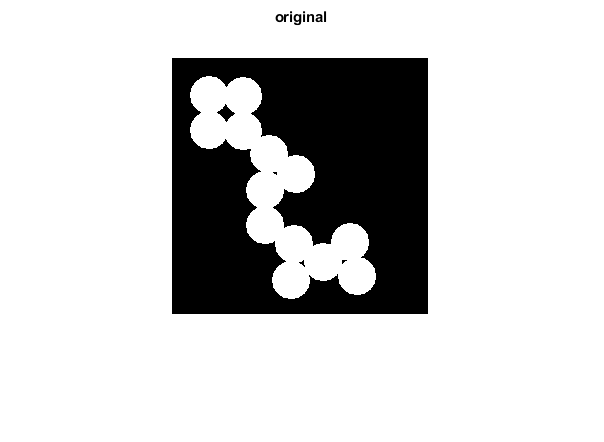

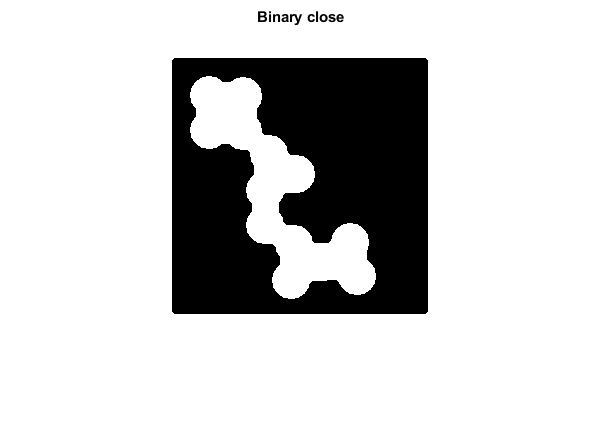

Image4 = imread('whitebubble.png');
imshow(Image4), title('original')
se = strel('disk',7);
MorphologyClose = imclose(Image4,se);
imshow(MorphologyClose), title('Binary close')

- Skeletonization: First convert the original image data set to binary format using "imbinarize" function, then i use "bwskel" to skeletonize the image (reduces all objects in the picture to 1-pixel wide curved lines without changing the essential structure of the image).

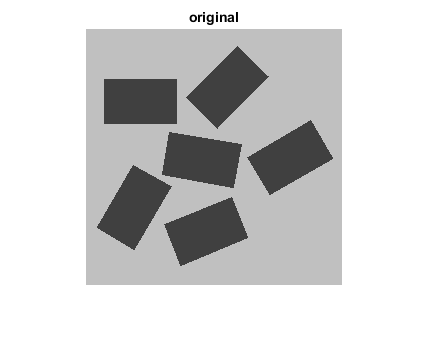

Image5 = imread('rect2.tif');
imshow(Image5), title('original')

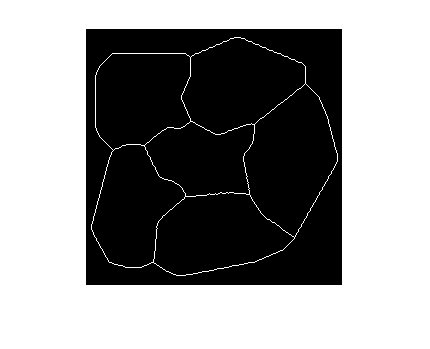

Skeleton = bwskel(imbinarize(Image5));
imshow(Skeleton)

**Q4:** Goal: Make your own demo for binary morphology. 

Ans: 

- **Erosion**: Shape: diamond

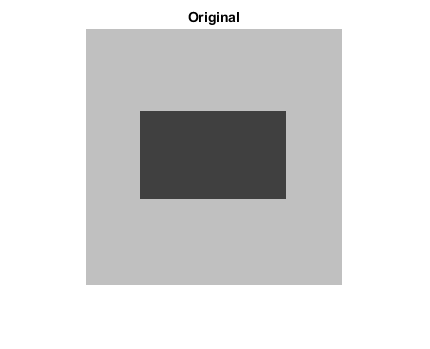

Image6 = imread('rect1.tif');
imshow(Image6), title('Original')

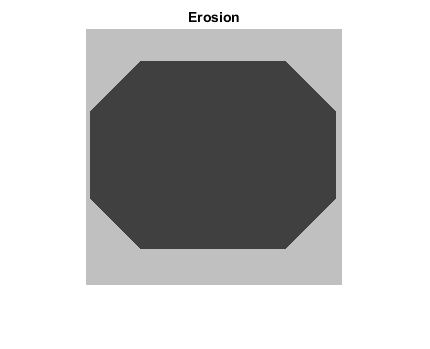

seDiamond1 = strel('diamond',50);
Erosion = imerode(Image6,seDiamond1);
imshow(Erosion), title('Erosion')

- **Dilation**: Shape: ball

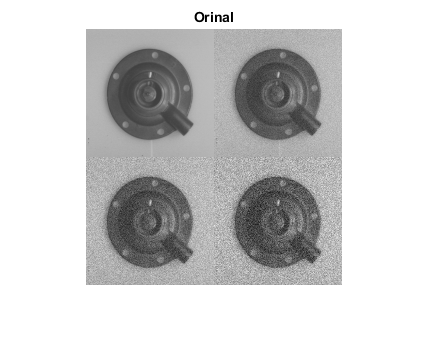

Image7 = imread('water.tif');
imshow(Image7), title('Orinal')

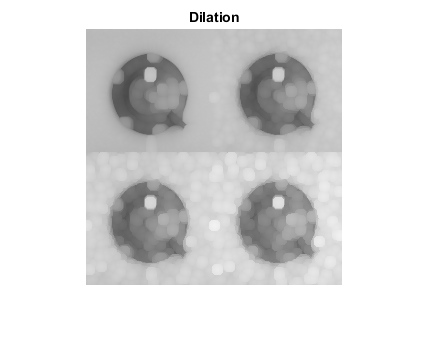

seDiamond2 = strel('ball',5,5);
Dilation= imdilate(Image7,seDiamond2);
imshow(Dilation), title('Dilation')

- **Binary Open**: Shape: disk

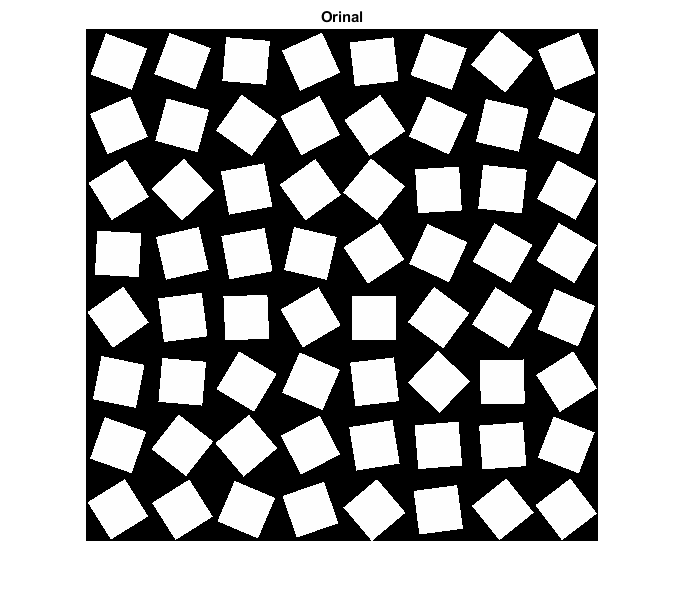

Image8 = imread('srect3.tif');
imshow(Image8), title('Orinal')

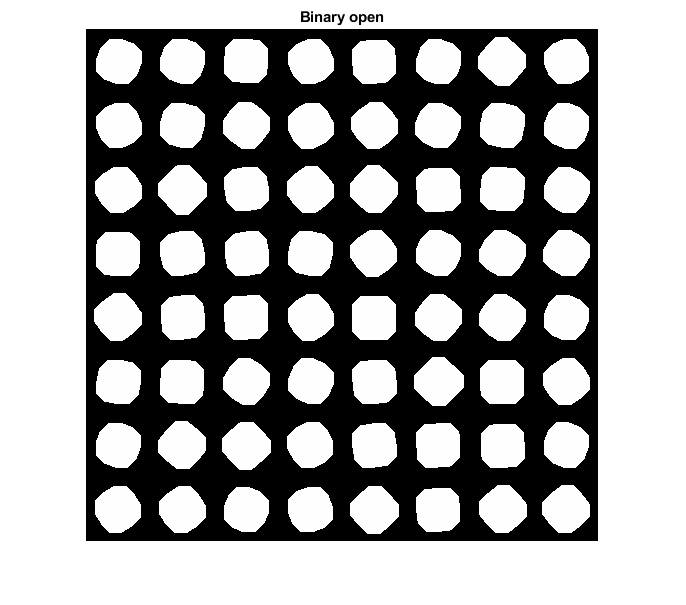

se = strel('disk',15);
MorphologyOpen = imopen(Image8,se);
imshow(MorphologyOpen), title('Binary open')

- **Binary Close**: Shape: disk

Image8 = imread('srect3.tif');
imshow(Image8), title('Orinal')

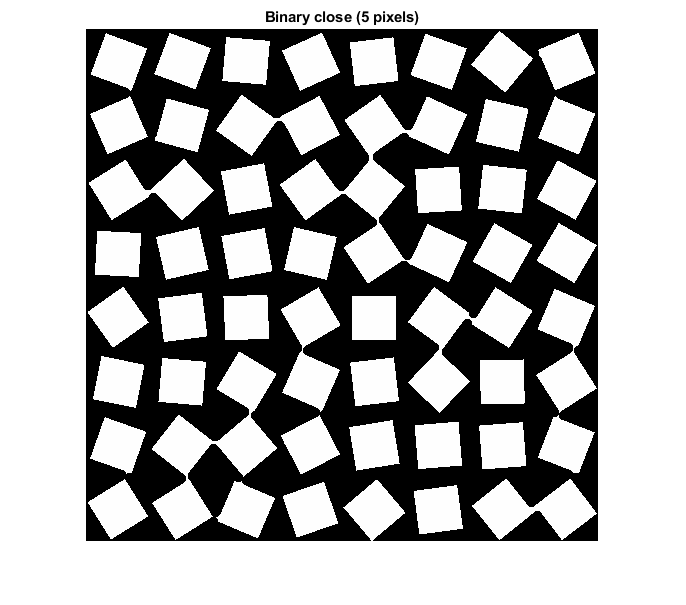

se = strel('disk',5);
MorphologyOpen = imclose(Image8,se);
imshow(MorphologyOpen), title('Binary close (5 pixels)')

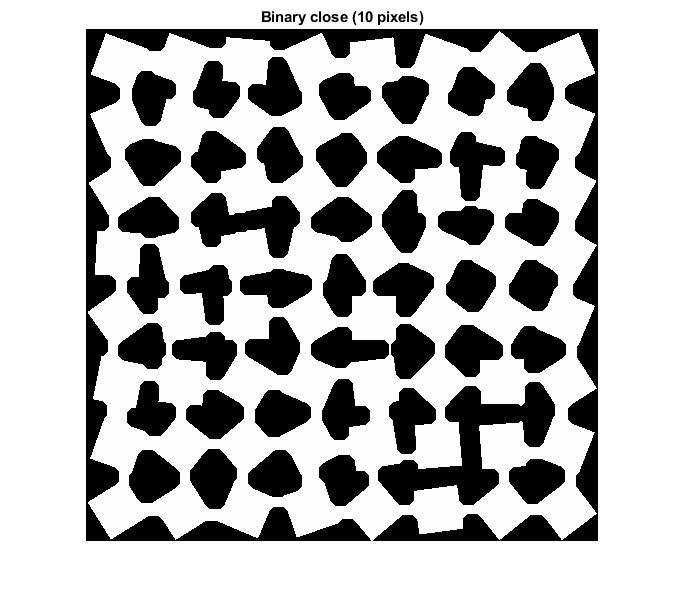

se = strel('disk',10);
MorphologyOpen = imclose(Image8,se);
imshow(MorphologyOpen), title('Binary close (10 pixels)')

**Q5:** Goal: implement in matlab to identify features based on shape. (you can choose your own images as well)

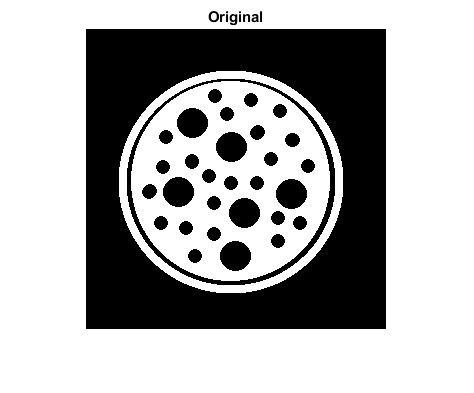

Image9 = imread('disk.png');
imshow(Image9), title('Original')

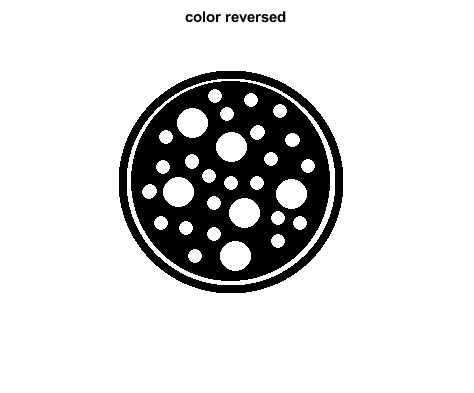

Image9 = imcomplement(Image9);%reverse the image's black and white
imshow(Image9), title('color reversed')

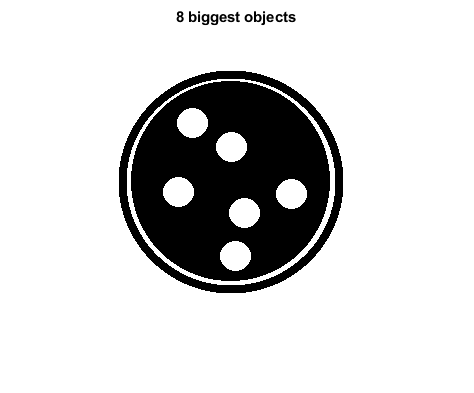

BW2 = bwareafilt(Image9, 8);
imshow(BW2),title('8 biggest objects')%filter 8 biggest objects of the picture

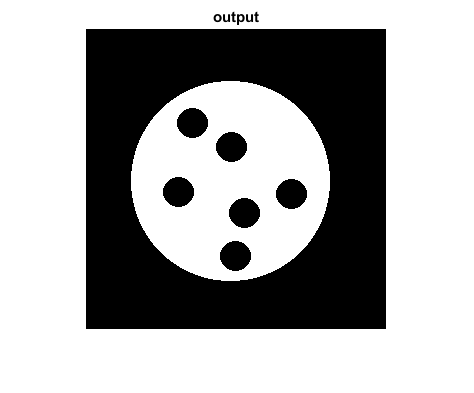

BW2 = imclearborder(BW2);%remove the border which is outside of the circles
BW2 = imcomplement(BW2);%reverse the image's black and white so it's back to orignal color
BW2 = imclearborder(BW2);%remove the outside border one more time
imshow(BW2), title('output')

**Q6:** Goal: implement in matlab for [**Morphological image Reconstruction**](https://nl.mathworks.com/help/images/ref/imreconstruct.html)(you can choose your own images as well)

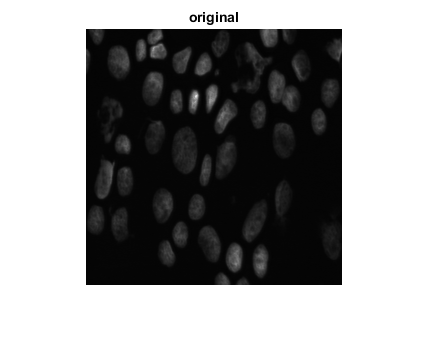

Image10 = imread('qdna.tif');
imshow(Image10), title('original')

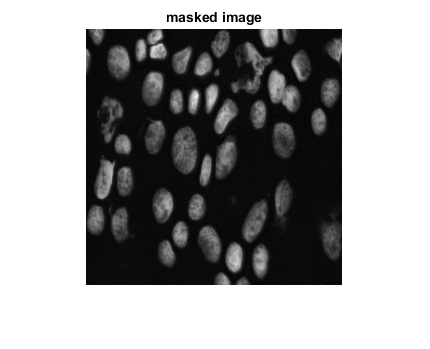

mask = adapthisteq(Image10);
%Adjust the contast of the image to create the mask image and display results.
imshow(mask), title('masked image')

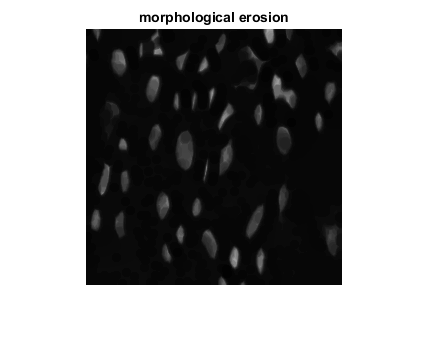

se = strel('disk',5);
marker = imerode(mask,se);
%Create a marker image that identifies high-intensity objects in the image 
%using morphological erosion and display results.
imshow(marker), title('morphological erosion')

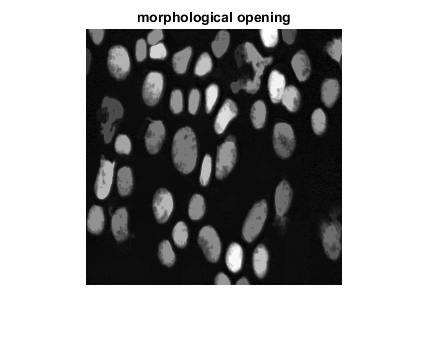

obr = imreconstruct(marker,mask);
%Perform morphological opening on the mask image, 
%using the marker image to identify high-intensity objects in the mask. Display results.
imshow(obr,[]), title('morphological opening')